# 時間相関Plotの作成

## ※デフォルトでは③：overlayのみPlotする

### ①beforeFit　

### ②afterFit　

### ③overlay (beforeFit+afterFit) 

folder_name_output = sprintf("output/%s/%s", DATE, sample_name);

folder_name_output = "output/221209/20nm"

if not(exist(folder_name_output,'dir'))
    mkdir(folder_name_output)
end

### ①beforeFit

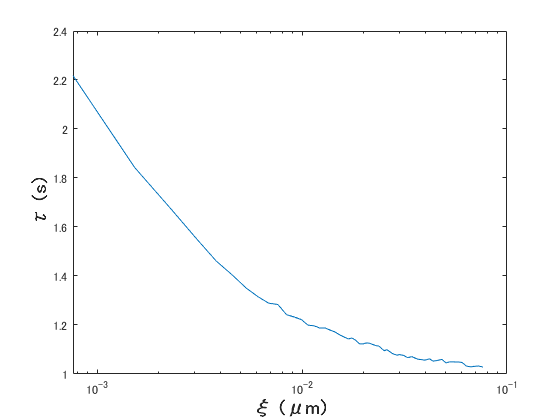

% %plot
% figure
% semilogx(TAU,COR)
% xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
% ylabel('τ (s)','FontSize',14,'FontWeight','bold');

% title(sprintf("時間相関 %s", sample_name));

### ②afterFit

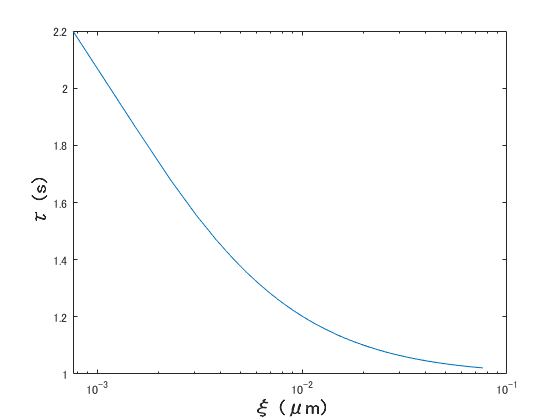

% %plot
% figure
% semilogx(TAU, modelfun_3dim_temporal(parms,TAU))
% xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
% ylabel('τ (s)','FontSize',14,'FontWeight','bold');

% title(sprintf("時間相関 %s", sample_name));

### ③overlay

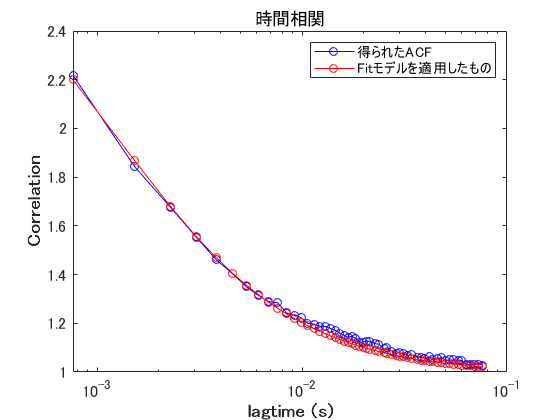

%plot
semilogx(TAU,COR, "b-o")
ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation", 'FontSize',14,'FontWeight','bold');

hold on;

semilogx(TAU, modelfun(parms,TAU), "r-o")
legend("得られたACF","Fitモデルを適用したもの", 'Location','northeast');

hold off;

%save figure
figurename = erase(filename, ".lsm");

%
if choice == 1
title(sprintf("時間相関 %s",sample_name));
saveas(gcf, sprintf("output/%s/%s/temporal_fitting %s.fig",DATE, sample_name,figurename))

saveas(gcf, sprintf("output/%s/png/temporal_fitting %s.png",DATE,figurename))
elseif choice == 5
title(sprintf("時間相関(定点X=%d) %s", constant_X,sample_name));
saveas(gcf, sprintf("output/%s/%s/temporal_fitting(定点X=%d) %s.fig",DATE, sample_name,constant_X,figurename))
saveas(gcf, sprintf("output/%s/png/temporal_fitting(定点X=%d) %s.png",DATE,constant_X,figurename))        
end